In many engineering problems, you will need to deal with multi dimensional problems.  For example, the air temperature in a room is a function of 3 spatial coordinates,  $x$, $y$ and $z$ and also time, $t$. So in "real" engineering application, the temperature in a room, $\theta$ is a function of 4 variables


$$\theta(x,y,z,t)$$


Visualising multidimensional function can be very useful but also very challenging.  We will illustrate the challenge by introducing you to the MATLAB tools to visualise functions with increasing number of variables.

Visualising a function of 1 variable is relatively straighforward.  If we want to plot


$$f(x)=xe^{-x^2}$$


we first define the domain for $x$ and then compute $f(x)$ and then plot $f(x)$ vs $x$.

x=-5:0.1:5  %define x domain -5<x<5

x =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


fx=x.*exp(-x.^2) % compute function

fx =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0004   -0.0006   -0.0011   -0.0018   -0.0030   -0.0048   -0.0076   -0.0116   -0.0174   -0.0255   -0.0366   -0.0514   -0.0705   -0.0945   -0.1237   -0.1581   -0.1972   -0.2399   -0.2843   -0.3280   -0.3679   -0.4004   -0.4218   -0.4288   -0.4186   -0.3894   -0.3409   -0.2742   -0.1922   -0.0990


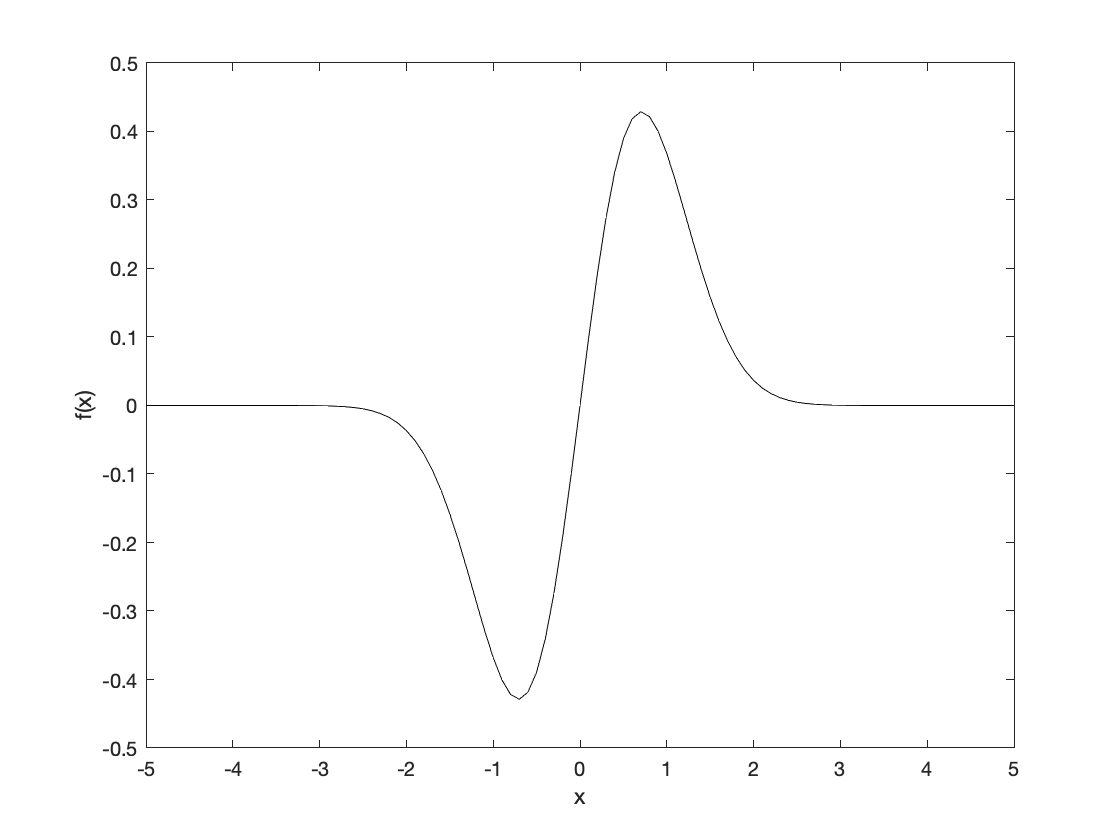

plot(x,fx,'k-')  % plot the function
xlabel('x')  %label horizontal axis
ylabel('f(x)') %label vertical axis

If you want to visualise functions of two variables, say


$$f(x,y)=50e^{-\left(x^2+y^2\right)/9^2}$$


then it is more complicated.  To visualise $f(x,y)$, you will need to follow the steps below.

- Define a two-dimensional mesh/grid.

- Evalute $f(x,y)$ on the mesh/grid.

- Plot the function using $\texttt{surf()}$ or $\texttt{contour()}$functions in MATLAB. 

The mesh/grid below 

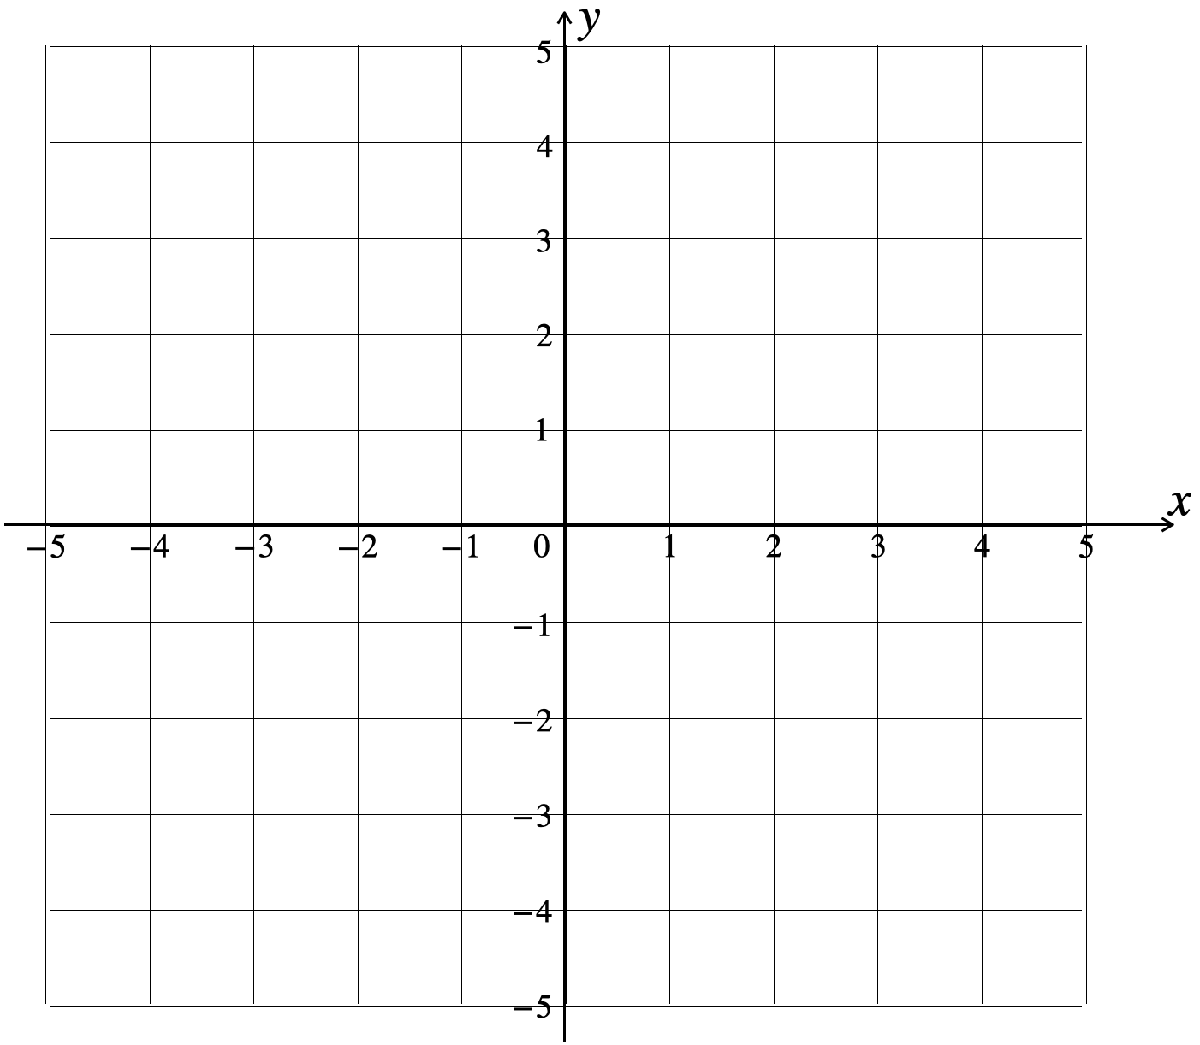

can be defined by the following lines of code

x=-5:1:5 % a 1-d vector consisting of 11 numbers from -5 to 5 [-5 -4 ..... 5]

x =     -5    -4    -3    -2    -1     0     1     2     3     4     5


y=-5:1:5 % a 1-d vector consisting of 11 numbers from -5 to 5 [-5 -4 ..... 5]

y =     -5    -4    -3    -2    -1     0     1     2     3     4     5


[X,Y]=meshgrid(x,y) % a 2-d matrix consisting of x and y above

X =     -5    -4    -3    -2    -1     0     1     2     3     4     5
    -5    -4    -3    -2    -1     0     1     2     3     4     5
    -5    -4    -3    -2    -1     0     1     2     3     4     5
    -5    -4    -3    -2    -1     0     1     2     3     4     5
    -5    -4    -3    -2    -1     0     1     2     3     4     5
    -5    -4    -3    -2    -1     0     1     2     3     4     5
    -5    -4    -3    -2    -1     0     1     2     3     4     5
    -5    -4    -3    -2    -1     0     1     2     3     4     5
    -5    -4    -3    -2    -1     0     1     2     3     4     5
    -5    -4    -3    -2    -1     0     1     2     3     4     5


Y =     -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3
     4     4     4     4     4     4     4     4     4     4     4


We evaluate the function $f(x,y)=50e^{-\left(x^2+y^2\right)/9^2}$ using the bit of code below

f=50.*exp(-(X.^2+Y.^2)/81)

f =    26.9704   30.1399   32.8605   34.9528   36.2716   36.7222   36.2716   34.9528   32.8605   30.1399   26.9704
   30.1399   33.6819   36.7222   39.0604   40.5342   41.0377   40.5342   39.0604   36.7222   33.6819   30.1399
   32.8605   36.7222   40.0369   42.5862   44.1930   44.7420   44.1930   42.5862   40.0369   36.7222   32.8605
   34.9528   39.0604   42.5862   45.2978   47.0069   47.5908   47.0069   45.2978   42.5862   39.0604   34.9528
   36.2716   40.5342   44.1930   47.0069   48.7805   49.3865   48.7805   47.0069   44.1930   40.5342   36.2716
   36.7222   41.0377   44.7420   47.5908   49.3865   50.0000   49.3865   47.5908   44.7420   41.0377   36.7222
   36.2716   40.5342   44.1930   47.0069   48.7805   49.3865   48.7805   47.0069   44.1930   40.5342   36.2716
   34.9528   39.0604   42.5862   45.2978   47.0069   47.5908   47.0069   45.2978   42.5862   39.0604   34.9528
   32.8605   36.7222   40.0369   42.5862   44.1930   44.7420   44.1930   42.5862   40.0369   36.7222   32.86

plot the function f with the grid defined by X and Y using the MATLAB $\texttt{contour()}$function. 

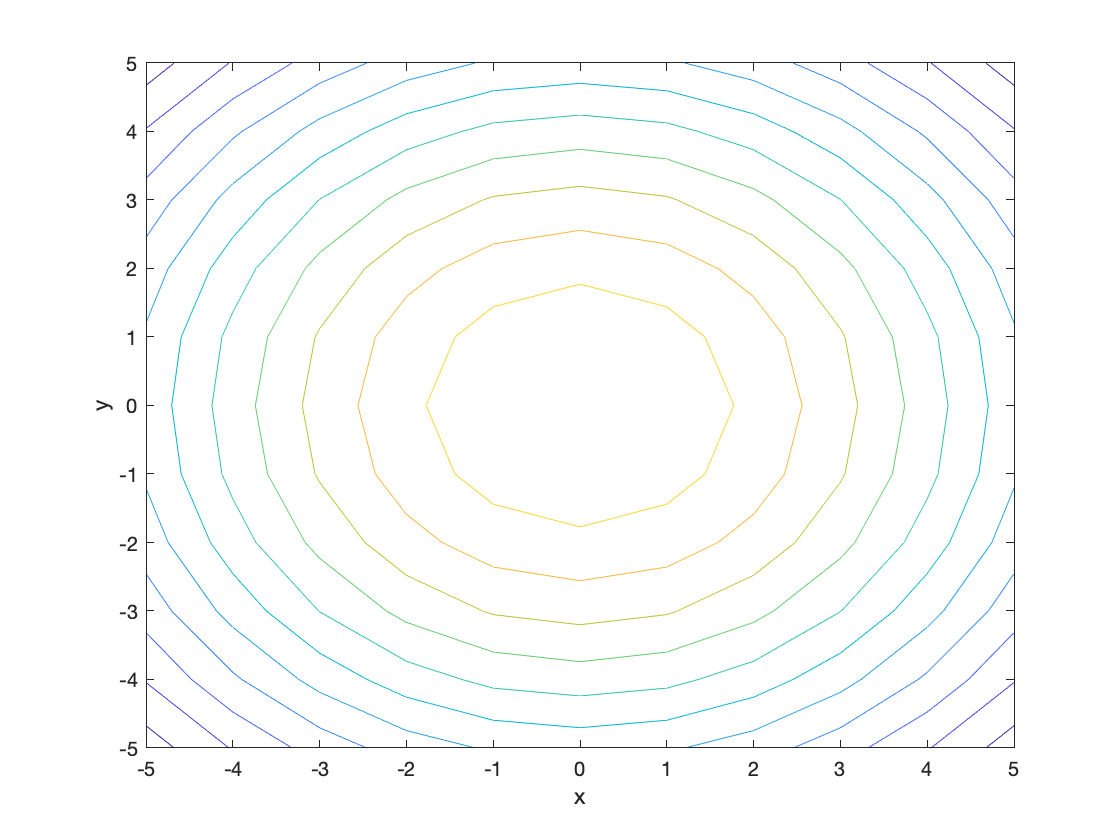

contour(X,Y,f)
xlabel('x') %label the x axis
ylabel('y') %label the y axis

Alternatively, you can use the $\texttt{surf()}$MATLAB function

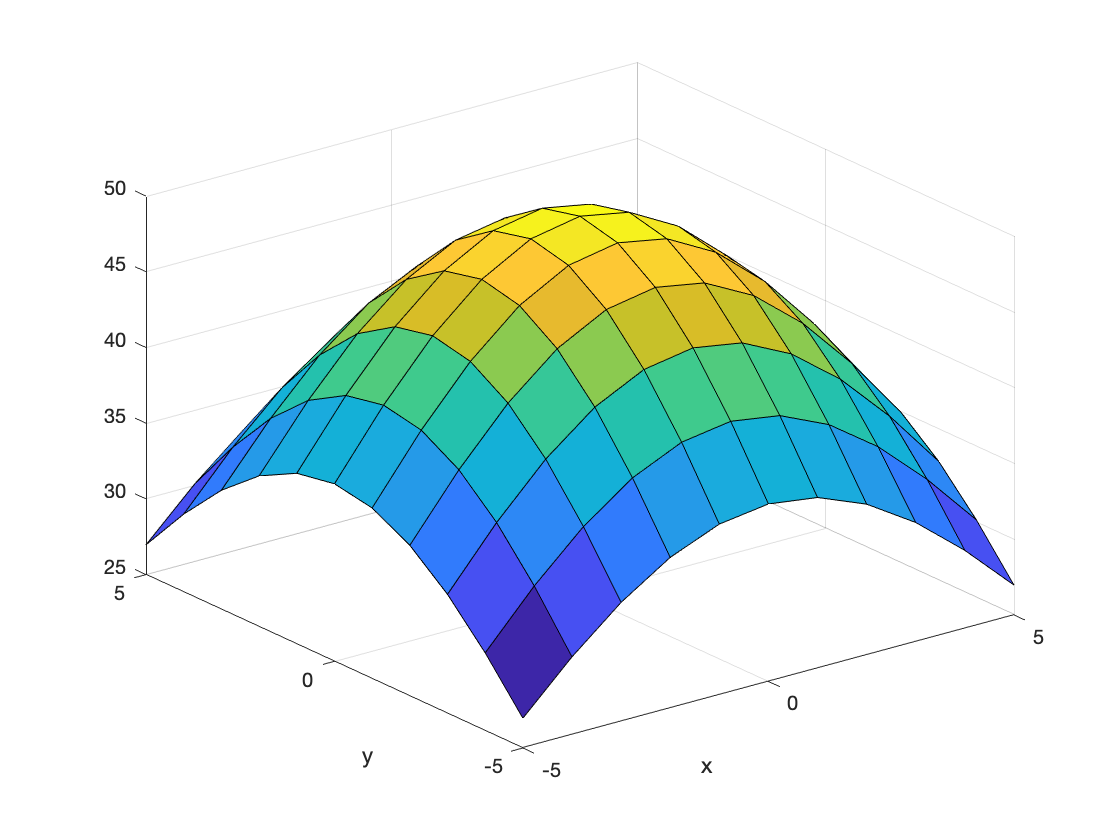

surf(X,Y,f)
xlabel('x') %label the x axis
ylabel('y') %label the y axis

One could also plot the function $f(x,y)=50e^{-\left(x^2+y^2\right)/9^2}$  at various contour levels where $f(x,y)=35, 40$ and 45. 

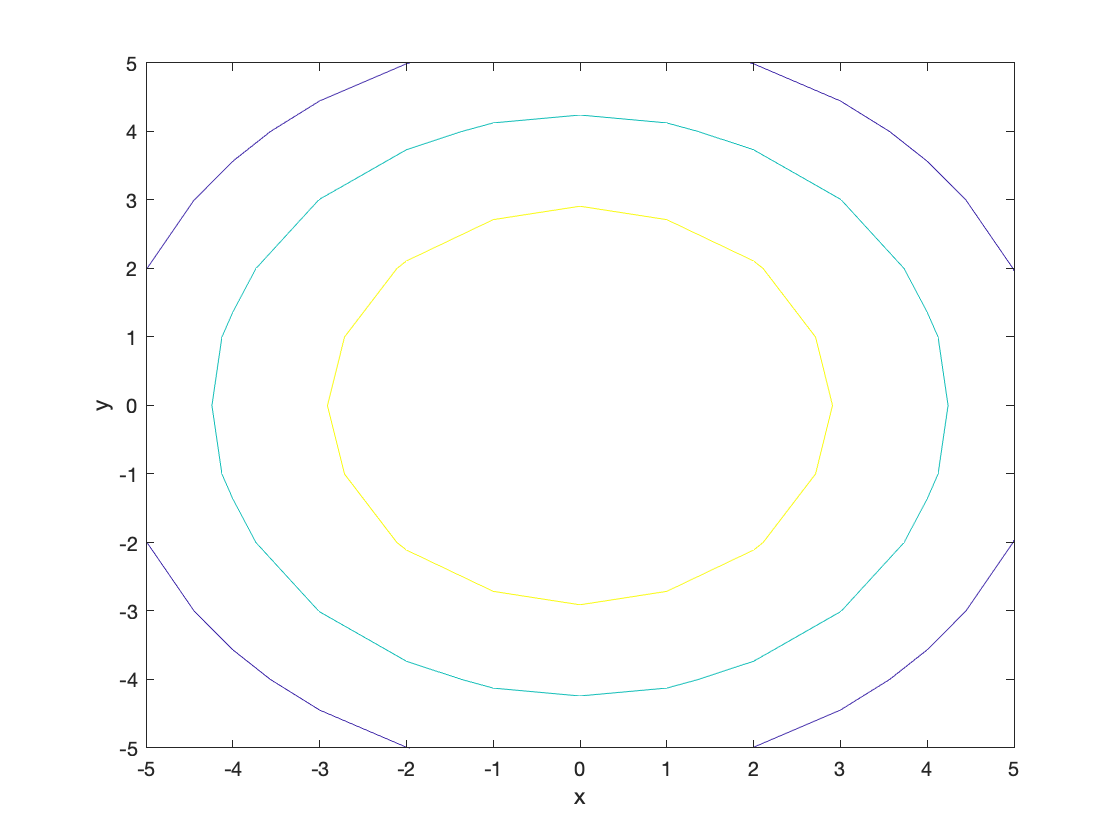

contour(X,Y,f, [35, 40 45])
xlabel('x') %label the x axis
ylabel('y') %label the y axis

The inner circle denotes the $(x,y)$values where $f(x,y)=45$. The outermost circle shows the $(x,y)$values where $f(x,y)=35$